# Lab 4 Exercise 1

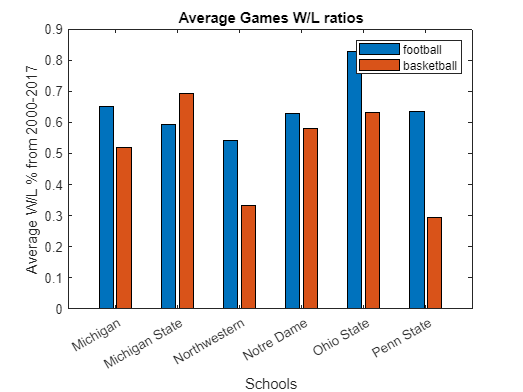

gameStatsPlot();

function avgWL = gameStatsPlot()

loopArr = ["B2:B20","C2:C20","D2:D20","E2:E20","F2:F20","G2:G20"];

ratioArr = [];
schoolArr = readmatrix("stats.xlsx", Sheet=1, Range="B1:G1",OutputType="string");
catSchArr = categorical(schoolArr);
tmpArr = schoolArr;
tmpFbArr=zeros(1,length(loopArr));
tmpBbArr=zeros(1,length(loopArr));
for i=1:length(loopArr)

fbWinningArr = readmatrix("stats.xlsx", Sheet=1, Range=loopArr(i));
fbTotalArr = readmatrix("stats.xlsx", Sheet=2, Range=loopArr(i));
fbRatioArr = fbWinningArr ./ fbTotalArr;
fbRatioAvgArr = sum(fbRatioArr)/length(fbRatioArr);

bbWinningArr = readmatrix("stats.xlsx", Sheet=3, Range=loopArr(i));
bbTotalArr = readmatrix("stats.xlsx", Sheet=4, Range=loopArr(i));
bbRatioArr = bbWinningArr ./ bbTotalArr;
bbRatioAvgArr = sum(bbRatioArr)/length(bbRatioArr);

tmpFbArr(i)=fbRatioAvgArr;
tmpBbArr(i)=bbRatioAvgArr;
end
tmpArr = cat(1,tmpArr, tmpFbArr,tmpBbArr);
%writematrix(tmpArr, "stats.xlsx", Sheet="ratios")
ratioArr = cat(1,ratioArr, tmpFbArr,tmpBbArr);


bar(catSchArr, ratioArr)
title('Average Games W/L ratios')
legend('football','basketball')
ylabel('Average W/L % from 2000-2017')
xlabel('Schools')
end